# KEVIN JAUKI

%% Environmental Brain Cube - Suitability Analysis
% This script looks at one suitability run from the log file.
%
% It does these things:
% - reads the suitability log
% - picks one run
% - works with old or new log format
% - compares values to expected ranges
% - checks if values seem stable or drifting
% - makes plots for all main variables
% - gives a simple long term decision

clear; clc; close all;

%% settings
fileName = "ebc_suitability_log.csv";
runChoice = "3";     % "latest" or a run number like "2" (make sure run number is accurate and quoted"")

showMinMaxBands = true;
showTrendLines = true;
useGroundTempInCore = true;

% prediction window settings
predictionMaxHours = 24;
predictionMinExtraFrac = 0.10;
predictionMaxExtraFrac = 0.80;

% settling OR trend behavior settings
prediction.recentFrac = 0.30;
prediction.startFrac = 0.20;
prediction.settleSlopeFrac = 0.35;
prediction.returnFrac = 0.25;
prediction.maxSettleHours = 8;
prediction.maxLinearHours = 24;
prediction.minPointsRecent = 6;

% prediction settings for battery / solar
prediction.minSlopeForLinear = 0.02;
prediction.energyMinSlopeForLinear = 0.05;
prediction.energySettleSlopeFrac = 0.20;

% curved prediction settings
prediction.allowCurved = true;
prediction.curveImproveFrac = 0.90;
prediction.minCurveStrength = 0.002;
prediction.maxCurveAccelFrac = 0.80;
prediction.curvePoints = 140;

% keep graph future time under control
prediction.graphMaxHours = 24;

% power settings
powerCfg.measuredSystemCurrentA = 0.09;     % measured max system draw
powerCfg.measuredSupplyVoltageV = 5.83;     % measured supply voltage
powerCfg.solarRatedVoltageV = 5.0;          % panel rated voltage
powerCfg.solarRatedCurrentA = 0.20;         % panel rated current
powerCfg.solarRatedPowerW = powerCfg.solarRatedVoltageV * powerCfg.solarRatedCurrentA;

% simple battery charge assumption
% this is just an estimate from available solar power
powerCfg.assumedBatteryVoltageV = 5.83;     % use measured supply side as simple estimate
powerCfg.assumedBatteryCapacitymAh = 500;   % change if using a different battery
powerCfg.chargeEfficiency = 0.80;           % assumed charging loss estimate

% EXPECTED RANGES
% should match Arduino code
expected.TempAirMin = 20.0;
expected.TempAirMax = 25.0;

expected.TempGroundMin = 20.0;
expected.TempGroundMax = 25.0;

expected.HumMin = 40.0;
expected.HumMax = 55.0;

expected.PresMin = 950.0;
expected.PresMax = 1050.0;

expected.BattMin = 5.00;
expected.BattMax = 7.20;

expected.SolarMin = 3.50;
expected.SolarMax = 5.50;

expected.LightMin = 0;
expected.LightMax = 4095;

expected.AxMin = -16.0; expected.AxMax = 16.0;
expected.AyMin = -16.0; expected.AyMax = 16.0;
expected.AzMin = -16.0; expected.AzMax = 16.0;

expected.GxMin = -250.0; expected.GxMax = 250.0;
expected.GyMin = -250.0; expected.GyMax = 250.0;
expected.GzMin = -250.0; expected.GzMax = 250.0;

%% long term decision settings
longTerm.centerGoodThreshold = 70;
longTerm.centerMarginalThreshold = 45;

longTerm.nearFutureHoursCritical = 24;
longTerm.nearFutureHoursWatch = 168;

longTerm.maxDriftTempC = 1.5;
longTerm.maxDriftHumPct = 5.0;
longTerm.maxDriftPreshPa = 3.0;
longTerm.maxDriftBattV = 0.25;
longTerm.maxDriftSolarV = 0.35;

longTerm.minDirectionalFraction = 0.70;
longTerm.windowFraction = 0.20;

%% check file
if ~isfile(fileName)
    error("File not found: " + fileName);
end

%% read file lines
txt = fileread(fileName);
lines = splitlines(string(txt));
lines = strtrim(lines);
lines = lines(lines ~= "");

%% keep only real run rows
dataLines = strings(0,1);

for i = 1:numel(lines)
    lineNow = lines(i);

    if startsWith(lineNow, "RUN") && ~startsWith(lineNow, "=== RUN")
        dataLines(end+1,1) = lineNow; %#ok<SAGROW>
    end
end

if isempty(dataLines)
    error("No valid RUN rows found.");
end

%% detect log format
firstParts = split(dataLines(1), ",");
numCols = numel(firstParts);

oldFormatCols = 19;
newFormatCols = 33;

if numCols == oldFormatCols
    logFormat = "old_single_value";
elseif numCols >= newFormatCols
    logFormat = "new_min_max";
else
    error("Unknown suitability log format. Found %d columns.", numCols);
end

fprintf("Detected log format: %s\n", logFormat);

Detected log format: new_min_max



%% create arrays
N = numel(dataLines);

runNum = nan(N,1);
timeSec = nan(N,1);

lightMin = nan(N,1); lightMax = nan(N,1); lightMid = nan(N,1); lightState = strings(N,1);

bmeTempMin = nan(N,1); bmeTempMax = nan(N,1); bmeTempMid = nan(N,1);
bmeHumMin  = nan(N,1); bmeHumMax  = nan(N,1); bmeHumMid  = nan(N,1);
bmePresMin = nan(N,1); bmePresMax = nan(N,1); bmePresMid = nan(N,1);
dsTempMin  = nan(N,1); dsTempMax  = nan(N,1); dsTempMid  = nan(N,1);

battMin = nan(N,1); battMax = nan(N,1); battMid = nan(N,1);
solarMin = nan(N,1); solarMax = nan(N,1); solarMid = nan(N,1);

axMin = nan(N,1); axMax = nan(N,1); axMid = nan(N,1);
ayMin = nan(N,1); ayMax = nan(N,1); ayMid = nan(N,1);
azMin = nan(N,1); azMax = nan(N,1); azMid = nan(N,1);

gxMin = nan(N,1); gxMax = nan(N,1); gxMid = nan(N,1);
gyMin = nan(N,1); gyMax = nan(N,1); gyMid = nan(N,1);
gzMin = nan(N,1); gzMax = nan(N,1); gzMid = nan(N,1);

tempWarn = nan(N,1);
humWarn = nan(N,1);
presWarn = nan(N,1);

%% read rows
for i = 1:N
    p = split(dataLines(i), ",");
    p = strtrim(p);

    runNum(i) = sscanf(p(1), "RUN%d");
    timeSec(i) = toNum(p(3));

    if logFormat == "old_single_value"
        lightMid(i) = toNum(p(4));
        lightMin(i) = lightMid(i);
        lightMax(i) = lightMid(i);
        lightState(i) = classifyLight(lightMid(i), 1000, 3800);

        bmeTempMid(i) = toNum(p(5));  bmeTempMin(i) = bmeTempMid(i);  bmeTempMax(i) = bmeTempMid(i);
        bmeHumMid(i)  = toNum(p(6));  bmeHumMin(i)  = bmeHumMid(i);   bmeHumMax(i)  = bmeHumMid(i);
        bmePresMid(i) = toNum(p(7));  bmePresMin(i) = bmePresMid(i);  bmePresMax(i) = bmePresMid(i);
        dsTempMid(i)  = toNum(p(8));  dsTempMin(i)  = dsTempMid(i);   dsTempMax(i)  = dsTempMid(i);

        battMid(i)  = toNum(p(9));   battMin(i)  = battMid(i);   battMax(i)  = battMid(i);
        solarMid(i) = toNum(p(10));  solarMin(i) = solarMid(i);  solarMax(i) = solarMid(i);

        axMid(i) = toNum(p(11)); axMin(i) = axMid(i); axMax(i) = axMid(i);
        ayMid(i) = toNum(p(12)); ayMin(i) = ayMid(i); ayMax(i) = ayMid(i);
        azMid(i) = toNum(p(13)); azMin(i) = azMid(i); azMax(i) = azMid(i);

        gxMid(i) = toNum(p(14)); gxMin(i) = gxMid(i); gxMax(i) = gxMid(i);
        gyMid(i) = toNum(p(15)); gyMin(i) = gyMid(i); gyMax(i) = gyMid(i);
        gzMid(i) = toNum(p(16)); gzMin(i) = gzMid(i); gzMax(i) = gzMid(i);

        tempWarn(i) = toNum(p(17));
        humWarn(i) = toNum(p(18));
        presWarn(i) = toNum(p(19));

    else
        lightMin(i) = toNum(p(4));
        lightMax(i) = toNum(p(5));
        lightMid(i) = mean([lightMin(i), lightMax(i)], 'omitnan');
        lightState(i) = string(p(6));

        bmeTempMin(i) = toNum(p(7));   bmeTempMax(i) = toNum(p(8));   bmeTempMid(i) = mean([bmeTempMin(i), bmeTempMax(i)], 'omitnan');
        bmeHumMin(i)  = toNum(p(9));   bmeHumMax(i)  = toNum(p(10));  bmeHumMid(i)  = mean([bmeHumMin(i), bmeHumMax(i)], 'omitnan');
        bmePresMin(i) = toNum(p(11));  bmePresMax(i) = toNum(p(12));  bmePresMid(i) = mean([bmePresMin(i), bmePresMax(i)], 'omitnan');
        dsTempMin(i)  = toNum(p(13));  dsTempMax(i)  = toNum(p(14));  dsTempMid(i)  = mean([dsTempMin(i), dsTempMax(i)], 'omitnan');

        battMin(i) = toNum(p(15));   battMax(i) = toNum(p(16));   battMid(i) = mean([battMin(i), battMax(i)], 'omitnan');
        solarMin(i) = toNum(p(17));  solarMax(i) = toNum(p(18));  solarMid(i) = mean([solarMin(i), solarMax(i)], 'omitnan');

        axMin(i) = toNum(p(19)); axMax(i) = toNum(p(20)); axMid(i) = mean([axMin(i), axMax(i)], 'omitnan');
        ayMin(i) = toNum(p(21)); ayMax(i) = toNum(p(22)); ayMid(i) = mean([ayMin(i), ayMax(i)], 'omitnan');
        azMin(i) = toNum(p(23)); azMax(i) = toNum(p(24)); azMid(i) = mean([azMin(i), azMax(i)], 'omitnan');

        gxMin(i) = toNum(p(25)); gxMax(i) = toNum(p(26)); gxMid(i) = mean([gxMin(i), gxMax(i)], 'omitnan');
        gyMin(i) = toNum(p(27)); gyMax(i) = toNum(p(28)); gyMid(i) = mean([gyMin(i), gyMax(i)], 'omitnan');
        gzMin(i) = toNum(p(29)); gzMax(i) = toNum(p(30)); gzMid(i) = mean([gzMin(i), gzMax(i)], 'omitnan');

        tempWarn(i) = toNum(p(31));
        humWarn(i) = toNum(p(32));
        presWarn(i) = toNum(p(33));
    end
end

%% make table
T = table(runNum,timeSec, ...
    lightMin,lightMax,lightMid,lightState, ...
    bmeTempMin,bmeTempMax,bmeTempMid, ...
    bmeHumMin,bmeHumMax,bmeHumMid, ...
    bmePresMin,bmePresMax,bmePresMid, ...
    dsTempMin,dsTempMax,dsTempMid, ...
    battMin,battMax,battMid, ...
    solarMin,solarMax,solarMid, ...
    axMin,axMax,axMid, ...
    ayMin,ayMax,ayMid, ...
    azMin,azMax,azMid, ...
    gxMin,gxMax,gxMid, ...
    gyMin,gyMax,gyMid, ...
    gzMin,gzMax,gzMid, ...
    tempWarn,humWarn,presWarn);

%% choose run
runs = unique(T.runNum);
runs = runs(~isnan(runs));

if isempty(runs)
    error("No valid runs found.");
end

if runChoice == "latest"
    runToUse = max(runs);
else
    runToUse = double(runChoice);
end

D = T(T.runNum == runToUse, :);
D = sortrows(D, "timeSec");

if isempty(D)
    error("Selected run not found.");
end

fprintf("Using RUN%d\n", runToUse);

Using RUN3


fprintf("Rows logged: %d\n", height(D));

Rows logged: 248


fprintf("Run duration: %.2f s\n", max(D.timeSec));

Run duration: 500.01 s



%% average values
runDurationSec = max(D.timeSec);

avgAirTemp = mean(D.bmeTempMid, 'omitnan');
avgGroundTemp = mean(D.dsTempMid, 'omitnan');
avgHum = mean(D.bmeHumMid, 'omitnan');
avgPres = mean(D.bmePresMid, 'omitnan');
avgBatt = mean(D.battMid, 'omitnan');
avgSolar = mean(D.solarMid, 'omitnan');
avgLight = mean(D.lightMid, 'omitnan');

avgAx = mean(D.axMid, 'omitnan');
avgAy = mean(D.ayMid, 'omitnan');
avgAz = mean(D.azMid, 'omitnan');

avgGx = mean(D.gxMid, 'omitnan');
avgGy = mean(D.gyMid, 'omitnan');
avgGz = mean(D.gzMid, 'omitnan');

summaryStats = table( ...
    avgAirTemp, avgGroundTemp, avgHum, avgPres, avgBatt, avgSolar, avgLight, ...
    avgAx, avgAy, avgAz, avgGx, avgGy, avgGz, ...
    'VariableNames', {'AvgAirTemp','AvgGroundTemp','AvgHumidity','AvgPressure', ...
    'AvgBattery','AvgSolar','AvgLight','AvgAx','AvgAy','AvgAz','AvgGx','AvgGy','AvgGz'});

disp("Run average values:")

Run average values:


disp(summaryStats)

    AvgAirTemp    AvgGroundTemp    AvgHumidity    AvgPressure    AvgBattery    AvgSolar    AvgLight     AvgAx      AvgAy      AvgAz      AvgGx     AvgGy     AvgGz 
    __________    _____________    ___________    ___________    __________    ________    ________    _______    ________    ______    _______    _____    _______

      22.782         20.447          46.284         1008.1         5.7183       4.7869      3781.9     0.31395    -0.71393    8.9636    0.88518    1.047    -1.6077




%% compare averages to expected ranges
[airPass, airClose, airOffset] = compareToRange(avgAirTemp, expected.TempAirMin, expected.TempAirMax);
[groundPass, groundClose, groundOffset] = compareToRange(avgGroundTemp, expected.TempGroundMin, expected.TempGroundMax);
[humPass, humClose, humOffset] = compareToRange(avgHum, expected.HumMin, expected.HumMax);
[presPass, presClose, presOffset] = compareToRange(avgPres, expected.PresMin, expected.PresMax);

[battPass, battClose, battOffset] = compareToRange(avgBatt, expected.BattMin, expected.BattMax);
[solarPass, solarClose, solarOffset] = compareToRange(avgSolar, expected.SolarMin, expected.SolarMax);
[lightPass, lightClose, lightOffset] = compareToRange(avgLight, expected.LightMin, expected.LightMax);

[axPass, axClose, axOffset] = compareToRange(avgAx, expected.AxMin, expected.AxMax);
[ayPass, ayClose, ayOffset] = compareToRange(avgAy, expected.AyMin, expected.AyMax);
[azPass, azClose, azOffset] = compareToRange(avgAz, expected.AzMin, expected.AzMax);

[gxPass, gxClose, gxOffset] = compareToRange(avgGx, expected.GxMin, expected.GxMax);
[gyPass, gyClose, gyOffset] = compareToRange(avgGy, expected.GyMin, expected.GyMax);
[gzPass, gzClose, gzOffset] = compareToRange(avgGz, expected.GzMin, expected.GzMax);

Parameter = [ ...
    "Air Temperature"; "Ground Temperature"; "Humidity"; "Pressure"; ...
    "Battery"; "Solar"; "Light"; ...
    "Accel X"; "Accel Y"; "Accel Z"; ...
    "Gyro X"; "Gyro Y"; "Gyro Z"];

RunAverage = [ ...
    avgAirTemp; avgGroundTemp; avgHum; avgPres; ...
    avgBatt; avgSolar; avgLight; ...
    avgAx; avgAy; avgAz; ...
    avgGx; avgGy; avgGz];

TargetMin = [ ...
    expected.TempAirMin; expected.TempGroundMin; expected.HumMin; expected.PresMin; ...
    expected.BattMin; expected.SolarMin; expected.LightMin; ...
    expected.AxMin; expected.AyMin; expected.AzMin; ...
    expected.GxMin; expected.GyMin; expected.GzMin];

TargetMax = [ ...
    expected.TempAirMax; expected.TempGroundMax; expected.HumMax; expected.PresMax; ...
    expected.BattMax; expected.SolarMax; expected.LightMax; ...
    expected.AxMax; expected.AyMax; expected.AzMax; ...
    expected.GxMax; expected.GyMax; expected.GzMax];

Pass = [ ...
    airPass; groundPass; humPass; presPass; ...
    battPass; solarPass; lightPass; ...
    axPass; ayPass; azPass; ...
    gxPass; gyPass; gzPass];

ClosenessPercent = [ ...
    airClose; groundClose; humClose; presClose; ...
    battClose; solarClose; lightClose; ...
    axClose; ayClose; azClose; ...
    gxClose; gyClose; gzClose];

CenterOffsetPercent = [ ...
    airOffset; groundOffset; humOffset; presOffset; ...
    battOffset; solarOffset; lightOffset; ...
    axOffset; ayOffset; azOffset; ...
    gxOffset; gyOffset; gzOffset];

ComparisonTable = table(Parameter, RunAverage, TargetMin, TargetMax, ...
    Pass, ClosenessPercent, CenterOffsetPercent);

disp("Comparison to expected ranges:")

Comparison to expected ranges:


disp(ComparisonTable)

         Parameter          RunAverage    TargetMin    TargetMax    Pass     ClosenessPercent    CenterOffsetPercent
    ____________________    __________    _________    _________    _____    ________________    ___________________

    "Air Temperature"          22.782         20           25       true          88.716                11.284      
    "Ground Temperature"       20.447         20           25       true          17.868                82.132      
    "Humidity"                 46.284         40           55       true          83.793                16.207      
    "Pressure"                 1008.1        950         1050       true          83.735                16.265      
    "Battery"                  5.7183          5          7


%% trend and drift checks
timeHr = D.timeSec / 3600;

trend.airTemp = analyzeLongTermTrend(timeHr, D.bmeTempMid, expected.TempAirMin, expected.TempAirMax, ...
    longTerm.maxDriftTempC, longTerm.minDirectionalFraction, longTerm.windowFraction);

trend.groundTemp = analyzeLongTermTrend(timeHr, D.dsTempMid, expected.TempGroundMin, expected.TempGroundMax, ...
    longTerm.maxDriftTempC, longTerm.minDirectionalFraction, longTerm.windowFraction);

trend.humidity = analyzeLongTermTrend(timeHr, D.bmeHumMid, expected.HumMin, expected.HumMax, ...
    longTerm.maxDriftHumPct, longTerm.minDirectionalFraction, longTerm.windowFraction);

trend.pressure = analyzeLongTermTrend(timeHr, D.bmePresMid, expected.PresMin, expected.PresMax, ...
    longTerm.maxDriftPreshPa, longTerm.minDirectionalFraction, longTerm.windowFraction);

trend.battery = analyzeLongTermTrend(timeHr, D.battMid, expected.BattMin, expected.BattMax, ...
    longTerm.maxDriftBattV, longTerm.minDirectionalFraction, longTerm.windowFraction);

trend.solar = analyzeLongTermTrend(timeHr, D.solarMid, expected.SolarMin, expected.SolarMax, ...
    longTerm.maxDriftSolarV, longTerm.minDirectionalFraction, longTerm.windowFraction);

TrendSummary = table( ...
    ["Air Temp"; "Ground Temp"; "Humidity"; "Pressure"; "Battery"; "Solar"], ...
    [trend.airTemp.startEndDrift; trend.groundTemp.startEndDrift; trend.humidity.startEndDrift; ...
     trend.pressure.startEndDrift; trend.battery.startEndDrift; trend.solar.startEndDrift], ...
    [trend.airTemp.directionalFraction; trend.groundTemp.directionalFraction; trend.humidity.directionalFraction; ...
     trend.pressure.directionalFraction; trend.battery.directionalFraction; trend.solar.directionalFraction], ...
    [displayBoundaryTime(trend.airTemp); displayBoundaryTime(trend.groundTemp); displayBoundaryTime(trend.humidity); ...
     displayBoundaryTime(trend.pressure); displayBoundaryTime(trend.battery); displayBoundaryTime(trend.solar)], ...
    [string(trend.airTemp.behavior); string(trend.groundTemp.behavior); string(trend.humidity.behavior); ...
     string(trend.pressure.behavior); string(trend.battery.behavior); string(trend.solar.behavior)], ...
    'VariableNames', {'Parameter','StartEndDrift','DirectionalFraction','TimeToBoundaryHours','Behavior'});

disp("Trend summary:")

Trend summary:


disp(TrendSummary)

      Parameter      StartEndDrift    DirectionalFraction    TimeToBoundaryHours    Behavior
    _____________    _____________    ___________________    ___________________    ________

    "Air Temp"          -0.8096             0.61943                  NaN            "STABLE"
    "Ground Temp"       -0.3235             0.19838                  NaN            "STABLE"
    "Humidity"           1.8919             0.53441                  NaN            "STABLE"
    "Pressure"           0.1113             0.43725                  NaN            "STABLE"
    "Battery"           -0.1685             0.36437                  NaN            "STABLE"
    "Solar"             -0.1539             0.40891                  NaN            "STABLE"




%% power calculations
D.battPowerW = D.battMid * powerCfg.measuredSystemCurrentA;

avgBattPowerW = mean(D.battPowerW, 'omitnan');
maxBattPowerW = max(D.battPowerW, [], 'omitnan');
battEnergyWhRun = integratePowerWh(D.timeSec, D.battPowerW);

% direct measured supply reference
measuredSupplyPowerW = powerCfg.measuredSupplyVoltageV * powerCfg.measuredSystemCurrentA;

% solar side estimate from rated panel power scaled by logged solar voltage
solarVoltageFrac = max(0, min(1.20, D.solarMid / powerCfg.solarRatedVoltageV));
D.solarPowerEstW = powerCfg.solarRatedPowerW * solarVoltageFrac;

avgSolarPowerEstW = mean(D.solarPowerEstW, 'omitnan');
maxSolarPowerEstW = max(D.solarPowerEstW, [], 'omitnan');
solarEnergyEstWhRun = integratePowerWh(D.timeSec, D.solarPowerEstW);

% net margin
D.netPowerMarginW = D.solarPowerEstW - D.battPowerW;
avgNetPowerMarginW = mean(D.netPowerMarginW, 'omitnan');

% 24 h predicted voltage and power
battPred24hV = predictValueAtHours(D.timeSec, D.battMid, expected.BattMin, expected.BattMax, trend.battery, prediction, true, 24);
solarPred24hV = predictValueAtHours(D.timeSec, D.solarMid, expected.SolarMin, expected.SolarMax, trend.solar, prediction, true, 24);

if ~isnan(battPred24hV)
    battPred24hPowerW = battPred24hV * powerCfg.measuredSystemCurrentA;
else
    battPred24hPowerW = NaN;
end

if ~isnan(solarPred24hV)
    solarPred24hPowerW = powerCfg.solarRatedPowerW * max(0, min(1.20, solarPred24hV / powerCfg.solarRatedVoltageV));
else
    solarPred24hPowerW = NaN;
end

% battery voltage-drop check
battDropRateVph = min(0, trend.battery.recentSlopePerHour);

if isnan(battDropRateVph)
    battPowerDropAlignment = "NOT ENOUGH DATA";
elseif avgBattPowerW > 0 && battDropRateVph < 0
    battPowerDropAlignment = "ALIGNS";
elseif avgBattPowerW > 0 && abs(battDropRateVph) < 1e-6
    battPowerDropAlignment = "MOSTLY STABLE";
else
    battPowerDropAlignment = "MIXED";
end

% solar trend check
solarSlopeVph = trend.solar.recentSlopePerHour;

if isnan(solarSlopeVph)
    solarPowerTrendAlignment = "NOT ENOUGH DATA";
elseif avgSolarPowerEstW > avgBattPowerW && solarSlopeVph >= 0
    solarPowerTrendAlignment = "ALIGNS";
elseif avgSolarPowerEstW > avgBattPowerW && solarSlopeVph < 0
    solarPowerTrendAlignment = "HIGH BUT DROPPING";
elseif avgSolarPowerEstW <= avgBattPowerW && solarSlopeVph < 0
    solarPowerTrendAlignment = "ALIGNS";
else
    solarPowerTrendAlignment = "MIXED";
end

% battery charging estimate from solar surplus
% this is an assumed estimate, not a full battery model
batteryEnergyWhAssumed = (powerCfg.assumedBatteryCapacitymAh / 1000) * powerCfg.assumedBatteryVoltageV;

if avgNetPowerMarginW > 0
    chargeTimeHoursIdeal = batteryEnergyWhAssumed / avgNetPowerMarginW;
    chargeTimeHoursAdj = batteryEnergyWhAssumed / (avgNetPowerMarginW * powerCfg.chargeEfficiency);
else
    chargeTimeHoursIdeal = Inf;
    chargeTimeHoursAdj = Inf;
end

PowerSummary = table( ...
    avgBattPowerW, maxBattPowerW, battEnergyWhRun, ...
    avgSolarPowerEstW, maxSolarPowerEstW, solarEnergyEstWhRun, ...
    avgNetPowerMarginW, measuredSupplyPowerW, ...
    battPred24hV, battPred24hPowerW, ...
    solarPred24hV, solarPred24hPowerW, ...
    chargeTimeHoursIdeal, chargeTimeHoursAdj, ...
    string(battPowerDropAlignment), string(solarPowerTrendAlignment), ...
    'VariableNames', {'AvgBattPowerW','MaxBattPowerW','BattEnergyWhRun', ...
    'AvgSolarPowerEstW','MaxSolarPowerEstW','SolarEnergyEstWhRun', ...
    'AvgNetPowerMarginW','MeasuredSupplyPowerW', ...
    'BattPred24hV','BattPred24hPowerW', ...
    'SolarPred24hV','SolarPred24hPowerW', ...
    'ChargeTimeHrIdeal','ChargeTimeHrAdj', ...
    'BattPowerVsDrop','SolarPowerVsTrend'});

disp("Power summary:")

Power summary:


disp(PowerSummary)

    AvgBattPowerW    MaxBattPowerW    BattEnergyWhRun    AvgSolarPowerEstW    MaxSolarPowerEstW    SolarEnergyEstWhRun    AvgNetPowerMarginW    MeasuredSupplyPowerW    BattPred24hV    BattPred24hPowerW    SolarPred24hV    SolarPred24hPowerW    ChargeTimeHrIdeal    ChargeTimeHrAdj    BattPowerVsDrop     SolarPowerVsTrend 
    _____________    _____________    _______________    _________________    _________________    ___________________    __________________    ____________________    ____________    _________________    _____________


%% air temp vs ground temp
avgAirGroundDelta = mean(D.bmeTempMid - D.dsTempMid, 'omitnan');
maxAirGroundDelta = max(abs(D.bmeTempMid - D.dsTempMid), [], 'omitnan');

if nnz(~isnan(D.bmeTempMid) & ~isnan(D.dsTempMid)) >= 3
    airGroundCorr = corr(D.bmeTempMid, D.dsTempMid, 'Rows', 'complete');
else
    airGroundCorr = NaN;
end

ExtraSummary = table( ...
    avgAirGroundDelta, maxAirGroundDelta, airGroundCorr, ...
    'VariableNames', {'AvgAirMinusGroundTempC','MaxAbsAirGroundTempDiffC','AirGroundCorrelation'});

disp("Extra deductions:")

Extra deductions:


disp(ExtraSummary)

    AvgAirMinusGroundTempC    MaxAbsAirGroundTempDiffC    AirGroundCorrelation
    ______________________    ________________________    ____________________

            2.3354                      2.86                    0.95298       




%% long-term score
coreClosenessList = [airClose, humClose, presClose];

if useGroundTempInCore
    coreClosenessList = [coreClosenessList, groundClose];
end

coreAverageCloseness = mean(coreClosenessList, 'omitnan');

coreTrendPenalty = 0;
coreComments = strings(0,1);

[coreTrendPenalty, coreComments] = applyRealDriftPenalty( ...
    coreTrendPenalty, coreComments, "Air temperature", trend.airTemp, ...
    longTerm.nearFutureHoursCritical, longTerm.nearFutureHoursWatch);

if useGroundTempInCore
    [coreTrendPenalty, coreComments] = applyRealDriftPenalty( ...
        coreTrendPenalty, coreComments, "Ground temperature", trend.groundTemp, ...
        longTerm.nearFutureHoursCritical, longTerm.nearFutureHoursWatch);
end

[coreTrendPenalty, coreComments] = applyRealDriftPenalty( ...
    coreTrendPenalty, coreComments, "Humidity", trend.humidity, ...
    longTerm.nearFutureHoursCritical, longTerm.nearFutureHoursWatch);

[coreTrendPenalty, coreComments] = applyRealDriftPenalty( ...
    coreTrendPenalty, coreComments, "Pressure", trend.pressure, ...
    longTerm.nearFutureHoursCritical, longTerm.nearFutureHoursWatch);

longTermScore = max(0, coreAverageCloseness - coreTrendPenalty);
supportAverageCloseness = mean([battClose, solarClose, lightClose], 'omitnan');

coreFail = strcmp(trend.airTemp.behavior, "UNSAFE_RISING") || ...
           strcmp(trend.humidity.behavior, "UNSAFE_RISING") || ...
           strcmp(trend.pressure.behavior, "UNSAFE_RISING");

if useGroundTempInCore
    coreFail = coreFail || strcmp(trend.groundTemp.behavior, "UNSAFE_RISING");
end

if coreFail
    longTermDecision = "NOT IDEAL FOR LONG-TERM USE";
elseif longTermScore >= longTerm.centerGoodThreshold
    longTermDecision = "LIKELY SUITABLE LONG-TERM";
elseif longTermScore >= longTerm.centerMarginalThreshold
    longTermDecision = "MARGINALLY SUITABLE LONG-TERM";
else
    longTermDecision = "WATCH FOR NEAR-FUTURE ENVIRONMENTAL CHANGE";
end

%% warning percentages
tempWarnFraction = mean(D.tempWarn == 1, 'omitnan') * 100;
humWarnFraction = mean(D.humWarn == 1, 'omitnan') * 100;
presWarnFraction = mean(D.presWarn == 1, 'omitnan') * 100;

%% overall summary
OverallSummary = table( ...
    runToUse, runDurationSec, ...
    coreAverageCloseness, supportAverageCloseness, coreTrendPenalty, longTermScore, ...
    tempWarnFraction, humWarnFraction, presWarnFraction, ...
    string(longTermDecision), ...
    'VariableNames', {'Run','DurationSec','CoreAverageClosenessPct','SupportAverageClosenessPct', ...
    'CoreTrendPenalty','LongTermScorePct','TempWarnPct','HumWarnPct','PresWarnPct','LongTermDecision'});

disp("Overall suitability summary:")

Overall suitability summary:


disp(OverallSummary)

    Run    DurationSec    CoreAverageClosenessPct    SupportAverageClosenessPct    CoreTrendPenalty    LongTermScorePct    TempWarnPct    HumWarnPct    PresWarnPct           LongTermDecision        
    ___    ___________    _______________________    __________________________    ________________    ________________    ___________    __________    ___________    _______________________________

     3       500.01               68.528                       50.635                     0                 68.528              0             0              0         "MARGINALLY SUITABLE LONG-TERM"



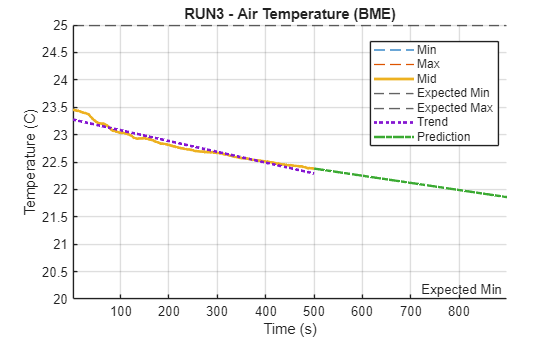


%% plots
plotVariableWithBand(D.timeSec, D.bmeTempMin, D.bmeTempMax, D.bmeTempMid, ...
    expected.TempAirMin, expected.TempAirMax, ...
    "Air Temperature (BME)", "Temperature (C)", runToUse, ...
    showMinMaxBands, showTrendLines, trend.airTemp, prediction, predictionMinExtraFrac, predictionMaxExtraFrac, false);

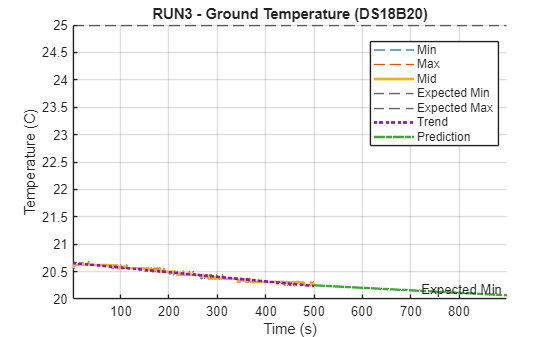


plotVariableWithBand(D.timeSec, D.dsTempMin, D.dsTempMax, D.dsTempMid, ...
    expected.TempGroundMin, expected.TempGroundMax, ...
    "Ground Temperature (DS18B20)", "Temperature (C)", runToUse, ...
    showMinMaxBands, showTrendLines, trend.groundTemp, prediction, predictionMinExtraFrac, predictionMaxExtraFrac, false);

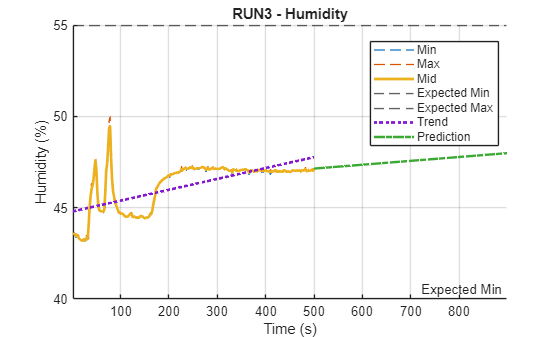


plotVariableWithBand(D.timeSec, D.bmeHumMin, D.bmeHumMax, D.bmeHumMid, ...
    expected.HumMin, expected.HumMax, ...
    "Humidity", "Humidity (%)", runToUse, ...
    showMinMaxBands, showTrendLines, trend.humidity, prediction, predictionMinExtraFrac, predictionMaxExtraFrac, false);

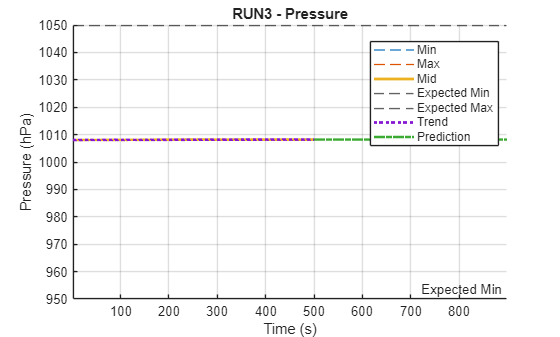


plotVariableWithBand(D.timeSec, D.bmePresMin, D.bmePresMax, D.bmePresMid, ...
    expected.PresMin, expected.PresMax, ...
    "Pressure", "Pressure (hPa)", runToUse, ...
    showMinMaxBands, showTrendLines, trend.pressure, prediction, predictionMinExtraFrac, predictionMaxExtraFrac, false);

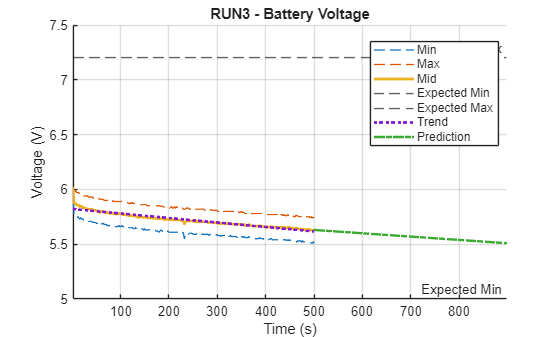


plotVariableWithBand(D.timeSec, D.battMin, D.battMax, D.battMid, ...
    expected.BattMin, expected.BattMax, ...
    "Battery Voltage", "Voltage (V)", runToUse, ...
    showMinMaxBands, showTrendLines, trend.battery, prediction, predictionMinExtraFrac, predictionMaxExtraFrac, true);

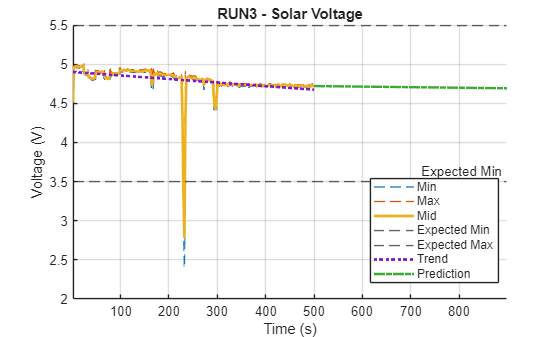


plotVariableWithBand(D.timeSec, D.solarMin, D.solarMax, D.solarMid, ...
    expected.SolarMin, expected.SolarMax, ...
    "Solar Voltage", "Voltage (V)", runToUse, ...
    showMinMaxBands, showTrendLines, trend.solar, prediction, predictionMinExtraFrac, predictionMaxExtraFrac, true);

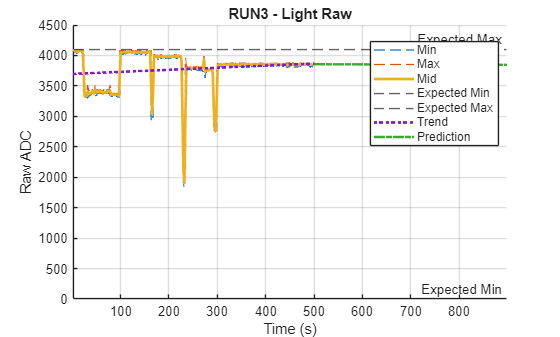


plotVariableWithBand(D.timeSec, D.lightMin, D.lightMax, D.lightMid, ...
    expected.LightMin, expected.LightMax, ...
    "Light Raw", "Raw ADC", runToUse, ...
    showMinMaxBands, showTrendLines, struct(), prediction, predictionMinExtraFrac, predictionMaxExtraFrac, false);

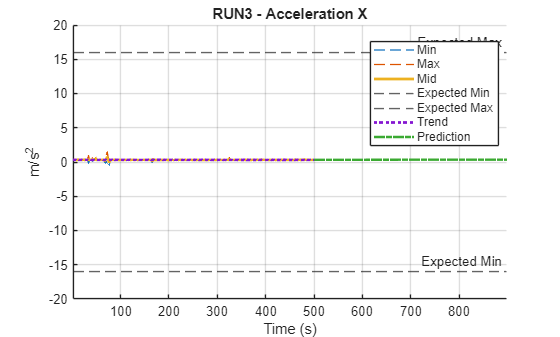


plotVariableWithBand(D.timeSec, D.axMin, D.axMax, D.axMid, ...
    expected.AxMin, expected.AxMax, ...
    "Acceleration X", "m/s^2", runToUse, ...
    showMinMaxBands, showTrendLines, struct(), prediction, predictionMinExtraFrac, predictionMaxExtraFrac, false);

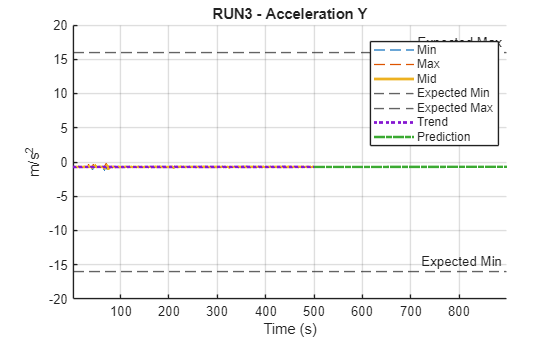


plotVariableWithBand(D.timeSec, D.ayMin, D.ayMax, D.ayMid, ...
    expected.AyMin, expected.AyMax, ...
    "Acceleration Y", "m/s^2", runToUse, ...
    showMinMaxBands, showTrendLines, struct(), prediction, predictionMinExtraFrac, predictionMaxExtraFrac, false);

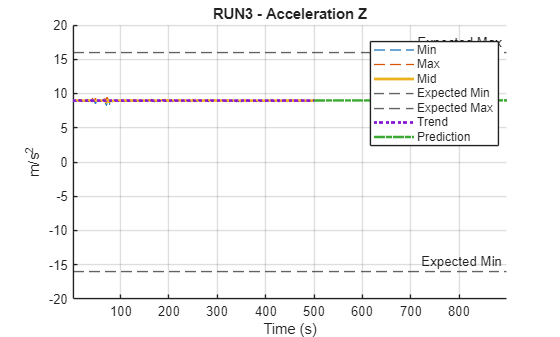


plotVariableWithBand(D.timeSec, D.azMin, D.azMax, D.azMid, ...
    expected.AzMin, expected.AzMax, ...
    "Acceleration Z", "m/s^2", runToUse, ...
    showMinMaxBands, showTrendLines, struct(), prediction, predictionMinExtraFrac, predictionMaxExtraFrac, false);

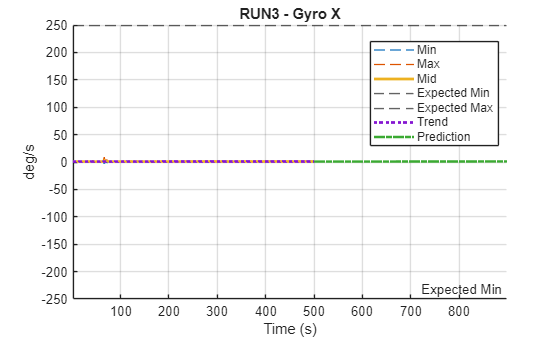


plotVariableWithBand(D.timeSec, D.gxMin, D.gxMax, D.gxMid, ...
    expected.GxMin, expected.GxMax, ...
    "Gyro X", "deg/s", runToUse, ...
    showMinMaxBands, showTrendLines, struct(), prediction, predictionMinExtraFrac, predictionMaxExtraFrac, false);

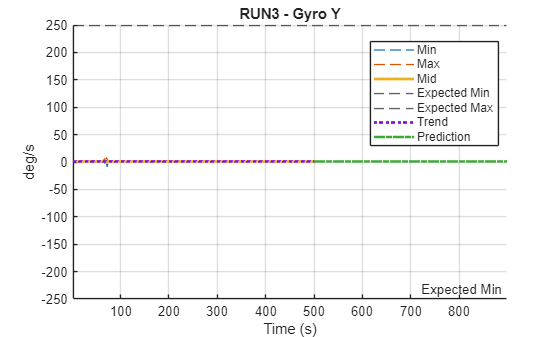


plotVariableWithBand(D.timeSec, D.gyMin, D.gyMax, D.gyMid, ...
    expected.GyMin, expected.GyMax, ...
    "Gyro Y", "deg/s", runToUse, ...
    showMinMaxBands, showTrendLines, struct(), prediction, predictionMinExtraFrac, predictionMaxExtraFrac, false);

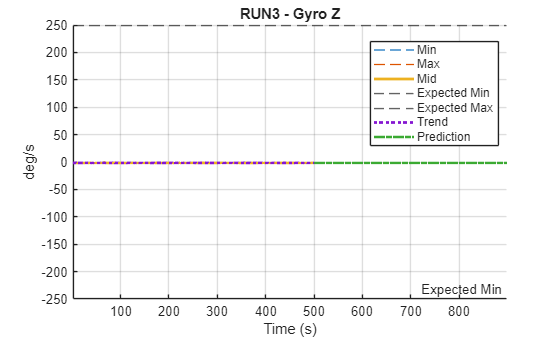


plotVariableWithBand(D.timeSec, D.gzMin, D.gzMax, D.gzMid, ...
    expected.GzMin, expected.GzMax, ...
    "Gyro Z", "deg/s", runToUse, ...
    showMinMaxBands, showTrendLines, struct(), prediction, predictionMinExtraFrac, predictionMaxExtraFrac, false);

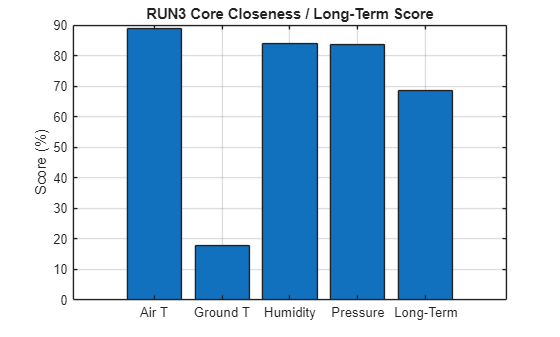


figure
bar([airClose, groundClose, humClose, presClose, longTermScore])
set(gca, 'XTickLabel', {'Air T','Ground T','Humidity','Pressure','Long-Term'})
ylabel('Score (%)')
title("RUN" + runToUse + " Core Closeness / Long-Term Score")
grid on

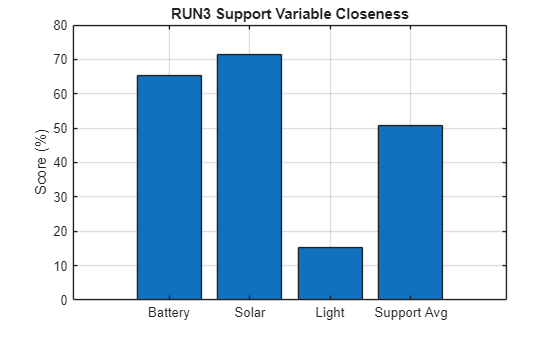


figure
bar([battClose, solarClose, lightClose, supportAverageCloseness])
set(gca, 'XTickLabel', {'Battery','Solar','Light','Support Avg'})
ylabel('Score (%)')
title("RUN" + runToUse + " Support Variable Closeness")
grid on

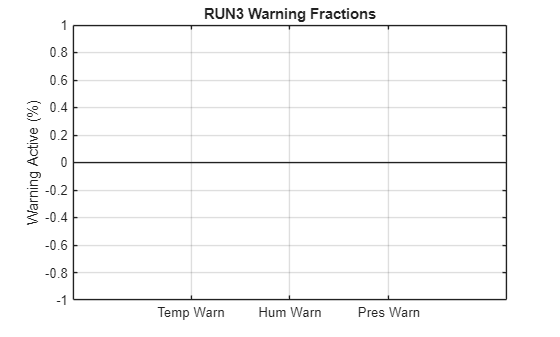


figure
bar([tempWarnFraction, humWarnFraction, presWarnFraction])
set(gca, 'XTickLabel', {'Temp Warn','Hum Warn','Pres Warn'})
ylabel('Warning Active (%)')
title("RUN" + runToUse + " Warning Fractions")
grid on

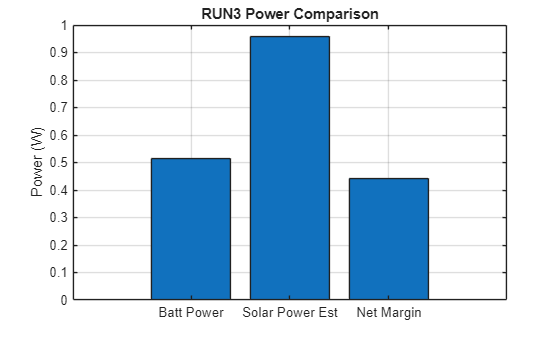


figure
bar([avgBattPowerW, avgSolarPowerEstW, avgNetPowerMarginW])
set(gca, 'XTickLabel', {'Batt Power','Solar Power Est','Net Margin'})
ylabel('Power (W)')
title("RUN" + runToUse + " Power Comparison")
grid on


%% conclusions
fprintf('\n============= SUITABILITY ANALYSIS =============\n');


============= SUITABILITY ANALYSIS =============


fprintf('Run: RUN%d | Duration: %.2f s | Format: %s\n', runToUse, runDurationSec, logFormat);

Run: RUN3 | Duration: 500.01 s | Format: new_min_max



fprintf('\nAverages:\n');


Averages:


fprintf('- Air: %.2f C | Ground: %.2f C | Humidity: %.2f %% | Pressure: %.2f hPa\n', ...
    avgAirTemp, avgGroundTemp, avgHum, avgPres);

- Air: 22.78 C | Ground: 20.45 C | Humidity: 46.28 % | Pressure: 1008.13 hPa


fprintf('- Battery: %.2f V | Solar: %.2f V | Light: %.2f\n', ...
    avgBatt, avgSolar, avgLight);

- Battery: 5.72 V | Solar: 4.79 V | Light: 3781.91



fprintf('\nCore check:\n');


Core check:


fprintf('- Air %.1f%% | Ground %.1f%% | Humidity %.1f%% | Pressure %.1f%%\n', ...
    airClose, groundClose, humClose, presClose);

- Air 88.7% | Ground 17.9% | Humidity 83.8% | Pressure 83.7%



fprintf('\nPower check:\n');


Power check:


fprintf('- Battery avg power: %.3f W\n', avgBattPowerW);

- Battery avg power: 0.515 W


fprintf('- Solar avg power est: %.3f W\n', avgSolarPowerEstW);

- Solar avg power est: 0.957 W


fprintf('- Net margin: %.3f W\n', avgNetPowerMarginW);

- Net margin: 0.443 W


fprintf('- Battery power vs drop: %s\n', battPowerDropAlignment);

- Battery power vs drop: ALIGNS


fprintf('- Solar power vs trend: %s\n', solarPowerTrendAlignment);

- Solar power vs trend: HIGH BUT DROPPING



if isfinite(chargeTimeHoursAdj)
    fprintf('- Est. battery charge time from solar: %.2f hr ideal, %.2f hr adjusted\n', ...
        chargeTimeHoursIdeal, chargeTimeHoursAdj);
else
    fprintf('- Est. battery charge time from solar: not supported by current average solar margin\n');
end

- Est. battery charge time from solar: 6.58 hr ideal, 8.23 hr adjusted



fprintf('\nTrend notes:\n');


Trend notes:


printTrend("Air", trend.airTemp);

- Air: drift = -0.810, directional consistency = 0.62, behavior = STABLE | no boundary estimate needed


printTrend("Ground", trend.groundTemp);

- Ground: drift = -0.324, directional consistency = 0.20, behavior = STABLE | no boundary estimate needed


printTrend("Humidity", trend.humidity);

- Humidity: drift = 1.892, directional consistency = 0.53, behavior = STABLE | no boundary estimate needed


printTrend("Pressure", trend.pressure);

- Pressure: drift = 0.111, directional consistency = 0.44, behavior = STABLE | no boundary estimate needed


printTrend("Battery", trend.battery);

- Battery: drift = -0.169, directional consistency = 0.36, behavior = STABLE | no boundary estimate needed


printTrend("Solar", trend.solar);

- Solar: drift = -0.154, directional consistency = 0.41, behavior = STABLE | no boundary estimate needed



fprintf('\nOther notes:\n');


Other notes:


fprintf('- Avg air-ground temp diff: %.3f C\n', avgAirGroundDelta);

- Avg air-ground temp diff: 2.335 C


if ~isnan(airGroundCorr)
    fprintf('- Air-ground temp correlation: %.3f\n', airGroundCorr);
end

- Air-ground temp correlation: 0.953



fprintf('\nResult:\n');


Result:


fprintf('- Long-term score: %.1f %%\n', longTermScore);

- Long-term score: 68.5 %


fprintf('- Decision: %s\n', longTermDecision);

- Decision: MARGINALLY SUITABLE LONG-TERM



if ~isempty(coreComments)
    fprintf('- Notes:\n');
    for i = 1:numel(coreComments)
        fprintf('  * %s\n', coreComments(i));
    end
end

fprintf('===============================================\n');


%% local functions
function x = toNum(s)
    s = strtrim(string(s));

    if s == "NA" || s == ""
        x = NaN;
    else
        x = str2double(s);
    end
end

function out = classifyLight(v, darkTh, brightTh)
    if isnan(v)
        out = "NA";
    elseif v <= darkTh
        out = "DARK";
    elseif v < brightTh
        out = "NORMAL";
    else
        out = "BRIGHT";
    end
end

function [isPass, closeness, centerOffsetPercent] = compareToRange(v, vMin, vMax)
    if isnan(v) || isnan(vMin) || isnan(vMax) || (vMax <= vMin)
        isPass = false;
        closeness = NaN;
        centerOffsetPercent = NaN;
        return
    end

    center = (vMin + vMax) / 2;
    halfRange = (vMax - vMin) / 2;

    centerOffsetPercent = abs(v - center) / halfRange * 100;
    closeness = max(0, 100 - centerOffsetPercent);
    isPass = (v >= vMin) && (v <= vMax);
end

function tr = analyzeLongTermTrend(tHr, y, yMin, yMax, maxAllowedDrift, minDirectionalFraction, windowFraction)
    good = ~(isnan(tHr) | isnan(y));
    tHr = tHr(good);
    y = y(good);

    tr.startEndDrift = NaN;
    tr.directionalFraction = NaN;
    tr.slopePerHour = NaN;
    tr.recentSlopePerHour = NaN;
    tr.timeToBoundaryHours = Inf;
    tr.behavior = "INSUFFICIENT_DATA";
    tr.trendingTowardLimit = false;
    tr.predictedEndValue24h = NaN;
    tr.startMean = NaN;
    tr.endMean = NaN;
    tr.settlingLike = false;

    if numel(y) < 5
        return
    end

    n = numel(y);
    w = max(2, round(windowFraction * n));

    yStart = mean(y(1:w), 'omitnan');
    yEnd = mean(y(end-w+1:end), 'omitnan');
    drift = yEnd - yStart;

    tr.startMean = yStart;
    tr.endMean = yEnd;
    tr.startEndDrift = drift;

    dy = diff(y);

    if drift > 0
        dirFrac = mean(dy > 0, 'omitnan');
    elseif drift < 0
        dirFrac = mean(dy < 0, 'omitnan');
    else
        dirFrac = 0.5;
    end

    tr.directionalFraction = dirFrac;

    pAll = polyfit(tHr, y, 1);
    tr.slopePerHour = pAll(1);

    recentStartIdx = max(1, n - max(3, round(0.30 * n)) + 1);
    tRecent = tHr(recentStartIdx:end);
    yRecent = y(recentStartIdx:end);

    if numel(yRecent) >= 3
        pRecent = polyfit(tRecent, yRecent, 1);
        tr.recentSlopePerHour = pRecent(1);
    end

    yNow = y(end);

    if ~isnan(tr.recentSlopePerHour)
        tr.predictedEndValue24h = yNow + tr.recentSlopePerHour * 24;
    end

    slopeSettling = false;
    if ~isnan(tr.slopePerHour) && ~isnan(tr.recentSlopePerHour) && abs(tr.slopePerHour) > eps
        slopeSettling = abs(tr.recentSlopePerHour) <= 0.35 * abs(tr.slopePerHour);
    end

    returningTowardStart = false;
    if ~isnan(yStart)
        returningTowardStart = abs(yNow - yStart) < abs(yEnd - yStart) + 1e-9;
    end

    flattening = false;
    recentHalf = floor(numel(yRecent)/2);
    if recentHalf >= 2
        p1 = polyfit(tRecent(1:recentHalf), yRecent(1:recentHalf), 1);
        p2 = polyfit(tRecent(recentHalf:end), yRecent(recentHalf:end), 1);
        flattening = abs(p2(1)) < abs(p1(1));
    end

    tr.settlingLike = slopeSettling || returningTowardStart || flattening;

    if abs(drift) <= maxAllowedDrift
        tr.behavior = "STABLE";

    elseif dirFrac < minDirectionalFraction
        tr.behavior = "TEMPORARY_BUMP";

    elseif tr.settlingLike
        tr.behavior = "SETTLING";

    else
        slopeToUse = tr.recentSlopePerHour;
        if isnan(slopeToUse)
            slopeToUse = tr.slopePerHour;
        end

        if slopeToUse > 0
            tr.trendingTowardLimit = yNow < yMax;
            if tr.trendingTowardLimit
                dt = (yMax - yNow) / slopeToUse;
                if dt > 0
                    tr.timeToBoundaryHours = dt;
                end
            end
        elseif slopeToUse < 0
            tr.trendingTowardLimit = yNow > yMin;
            if tr.trendingTowardLimit
                dt = (yMin - yNow) / slopeToUse;
                if dt > 0
                    tr.timeToBoundaryHours = dt;
                end
            end
        end

        if isfinite(tr.timeToBoundaryHours) && tr.timeToBoundaryHours <= 24
            tr.behavior = "UNSAFE_RISING";
        elseif isfinite(tr.timeToBoundaryHours) && tr.timeToBoundaryHours <= 168
            tr.behavior = "WATCH";
        else
            tr.behavior = "SLOW_DRIFT";
        end
    end

    if any(strcmp(string(tr.behavior), ["STABLE","TEMPORARY_BUMP","SETTLING"]))
        tr.timeToBoundaryHours = Inf;
        tr.trendingTowardLimit = false;
    end
end

function [penalty, comments] = applyRealDriftPenalty(penalty, comments, name, tr, ~, watchHours)
    switch string(tr.behavior)
        case "STABLE"

        case "TEMPORARY_BUMP"
            comments(end+1,1) = name + " changed briefly, but not enough to count as real drift.";

        case "SETTLING"
            comments(end+1,1) = name + " looks like it is settling, so no continuing boundary estimate is needed.";

        case "SLOW_DRIFT"
            if isfinite(tr.timeToBoundaryHours) && tr.timeToBoundaryHours > watchHours
                comments(end+1,1) = name + " is drifting, but the boundary looks far away, so near-future risk is low.";
            else
                penalty = penalty + 8;
                comments(end+1,1) = name + " shows drift and should be watched.";
            end

        case "WATCH"
            penalty = penalty + 15;
            comments(end+1,1) = name + " is trending enough to affect the near future.";

        case "UNSAFE_RISING"
            penalty = penalty + 30;
            comments(end+1,1) = name + " is changing consistently enough to become unsafe soon.";

        otherwise
            penalty = penalty + 5;
            comments(end+1,1) = name + " did not have enough clear data for a strong prediction.";
    end
end

function txt = passText(tf)
    if tf
        txt = "PASS";
    else
        txt = "FAIL";
    end
end

function printTrend(name, tr)
    fprintf('- %s: ', name);

    if isnan(tr.startEndDrift)
        fprintf('insufficient data\n');
        return
    end

    fprintf('drift = %.3f, directional consistency = %.2f, behavior = %s', ...
        tr.startEndDrift, tr.directionalFraction, tr.behavior);

    if isfinite(tr.timeToBoundaryHours)
        fprintf(' | est. time to boundary = %.2f hr\n', tr.timeToBoundaryHours);
    else
        fprintf(' | no boundary estimate needed\n');
    end
end

function v = displayBoundaryTime(tr)
    if isfinite(tr.timeToBoundaryHours)
        v = tr.timeToBoundaryHours;
    else
        v = NaN;
    end
end

function energyWh = integratePowerWh(tSec, pW)
    good = ~(isnan(tSec) | isnan(pW));
    tSec = tSec(good);
    pW = pW(good);

    if numel(tSec) < 2
        energyWh = NaN;
        return
    end

    energyWh = trapz(tSec / 3600, pW);
end

function yPred = predictValueAtHours(tSec, y, expectedMin, expectedMax, tr, cfg, isEnergyVariable, hoursAhead)
    pred = buildPredictionPath(tSec, y, expectedMin, expectedMax, tr, cfg, isEnergyVariable);

    if isempty(pred.t)
        yPred = NaN;
        return
    end

    tTarget = max(tSec) + hoursAhead * 3600;

    if tTarget < pred.t(1) || tTarget > pred.t(end)
        yPred = NaN;
        return
    end

    yPred = interp1(pred.t, pred.y, tTarget, 'linear', NaN);
end

function pred = buildPredictionPath(tSec, y, expectedMin, expectedMax, tr, cfg, isEnergyVariable)
    pred.t = [];
    pred.y = [];
    pred.mode = "none";

    good = ~(isnan(tSec) | isnan(y));
    tSec = tSec(good);
    y = y(good);

    if numel(y) < max(6, cfg.minPointsRecent)
        return
    end

    n = numel(y);
    nRecent = max(cfg.minPointsRecent, round(cfg.recentFrac * n));
    nStart = max(3, round(cfg.startFrac * n));

    iRecent = max(1, n - nRecent + 1);

    tRecent = tSec(iRecent:end);
    yRecent = y(iRecent:end);

    startMean = mean(y(1:nStart), 'omitnan');
    recentMean = mean(yRecent, 'omitnan');
    lastVal = y(end);

    tRecentHr = (tRecent - tRecent(1)) / 3600;
    tLast = tSec(end);

    pRecent = polyfit(tRecent/3600, yRecent, 1);
    recentSlope = pRecent(1);

    pAll = polyfit(tSec/3600, y, 1);
    fullSlope = pAll(1);

    rangeWidth = expectedMax - expectedMin;
    if rangeWidth <= 0
        rangeWidth = max(abs(lastVal), 1);
    end

    if isEnergyVariable
        settleSlopeFracToUse = cfg.energySettleSlopeFrac;
        minSlopeForLinearToUse = cfg.energyMinSlopeForLinear;
    else
        settleSlopeFracToUse = cfg.settleSlopeFrac;
        minSlopeForLinearToUse = max(0.004, cfg.minSlopeForLinear * 0.25);
    end

    slopeSettling = false;
    if ~isnan(fullSlope) && ~isnan(recentSlope) && abs(fullSlope) > eps
        slopeSettling = abs(recentSlope) <= settleSlopeFracToUse * abs(fullSlope);
    end

    returningTowardStart = false;
    if ~isnan(startMean)
        distNow = abs(lastVal - startMean);
        distRecentMean = abs(recentMean - startMean);
        returningTowardStart = distNow <= distRecentMean + cfg.returnFrac * rangeWidth;
    end

    recentHalf = floor(numel(yRecent)/2);
    flattening = false;
    if recentHalf >= 2
        p1 = polyfit(tRecent(1:recentHalf)/3600, yRecent(1:recentHalf), 1);
        p2 = polyfit(tRecent(recentHalf:end)/3600, yRecent(recentHalf:end), 1);
        flattening = abs(p2(1)) < abs(p1(1));
    end

    strongRecentDrift = abs(recentSlope) >= minSlopeForLinearToUse;
    sameDirection = sign(recentSlope) == sign(fullSlope) || abs(fullSlope) < eps;

    if isEnergyVariable
        shouldSettle = false;
    else
        shouldSettle = ~strongRecentDrift && ...
            (slopeSettling || returningTowardStart || flattening || ...
             strcmp(string(tr.behavior),"TEMPORARY_BUMP") || ...
             strcmp(string(tr.behavior),"STABLE") || ...
             strcmp(string(tr.behavior),"SETTLING"));
    end

    if strongRecentDrift && sameDirection
        shouldSettle = false;
    end

    if shouldSettle
        target = recentMean;
        if abs(startMean - lastVal) < abs(recentMean - lastVal)
            target = startMean;
        end

        target = min(max(target, expectedMin), expectedMax);

        tFutureEnd = tLast + min(cfg.maxSettleHours, cfg.graphMaxHours) * 3600;
        tFuture = linspace(tLast, tFutureEnd, cfg.curvePoints);

        tau = max((min(cfg.maxSettleHours, cfg.graphMaxHours) * 3600)/4, 60);
        yFuture = target + (lastVal - target) * exp(-(tFuture - tLast)/tau);

        pred.mode = "settling";
        pred.t = tFuture;
        pred.y = yFuture;
        return
    end

    curveUsed = false;
    if cfg.allowCurved && numel(yRecent) >= 5
        pLinRecent = polyfit(tRecentHr, yRecent, 1);
        yLinRecent = polyval(pLinRecent, tRecentHr);

        pQuadRecent = polyfit(tRecentHr, yRecent, 2);
        yQuadRecent = polyval(pQuadRecent, tRecentHr);

        rmseLin = sqrt(mean((yRecent - yLinRecent).^2, 'omitnan'));
        rmseQuad = sqrt(mean((yRecent - yQuadRecent).^2, 'omitnan'));

        curveStrength = abs(2 * pQuadRecent(1));
        slopeAtEnd = 2 * pQuadRecent(1) * tRecentHr(end) + pQuadRecent(2);

        dataSpanHr = max(tRecentHr) - min(tRecentHr);
        if dataSpanHr <= 0
            dataSpanHr = 1;
        end

        maxAllowedAccel = cfg.maxCurveAccelFrac * max(abs(recentSlope), minSlopeForLinearToUse) / dataSpanHr;
        curveAccel = min(max(2 * pQuadRecent(1), -maxAllowedAccel), maxAllowedAccel);

        sameDirectionAsRecent = true;
        if abs(recentSlope) > eps && abs(slopeAtEnd) > eps
            sameDirectionAsRecent = sign(slopeAtEnd) == sign(recentSlope);
        end

        curveOkay = (rmseQuad <= cfg.curveImproveFrac * rmseLin || rmseLin < eps) && ...
                    (abs(curveStrength) >= cfg.minCurveStrength || abs(recentSlope) >= minSlopeForLinearToUse) && ...
                    sameDirectionAsRecent;

        if curveOkay
            maxFutureSec = min(cfg.maxLinearHours, cfg.graphMaxHours) * 3600;
            tFuture = linspace(tLast, tLast + maxFutureSec, cfg.curvePoints);
            dtHr = (tFuture - tLast) / 3600;
            yFuture = lastVal + slopeAtEnd * dtHr + 0.5 * curveAccel * dtHr.^2;

            idxStop = firstBoundaryHit(yFuture, expectedMin, expectedMax);
            if ~isempty(idxStop)
                tFuture = tFuture(1:idxStop);
                yFuture = yFuture(1:idxStop);
                yFuture(end) = min(max(yFuture(end), expectedMin), expectedMax);
            end

            if numel(yFuture) >= 2
                pred.mode = "curved";
                pred.t = tFuture;
                pred.y = yFuture;
                curveUsed = true;
            end
        end
    end

    if curveUsed
        return
    end

    maxFutureSec = min(cfg.maxLinearHours, cfg.graphMaxHours) * 3600;
    tBoundary = NaN;

    if recentSlope > 0 && lastVal < expectedMax
        dtHr = (expectedMax - lastVal) / recentSlope;
        if dtHr > 0
            tBoundary = tLast + dtHr * 3600;
        end
    elseif recentSlope < 0 && lastVal > expectedMin
        dtHr = (expectedMin - lastVal) / recentSlope;
        if dtHr > 0
            tBoundary = tLast + dtHr * 3600;
        end
    end

    if isnan(tBoundary)
        tEnd = tLast + maxFutureSec;
    else
        tEnd = min(tBoundary, tLast + maxFutureSec);
    end

    if tEnd <= tLast
        return
    end

    tFuture = linspace(tLast, tEnd, cfg.curvePoints);
    yFuture = lastVal + recentSlope * ((tFuture - tLast)/3600);

    if ~isnan(tBoundary) && abs(tFuture(end) - tBoundary) < 1
        if recentSlope > 0
            yFuture(end) = expectedMax;
        elseif recentSlope < 0
            yFuture(end) = expectedMin;
        end
    end

    pred.mode = "linear";
    pred.t = tFuture;
    pred.y = yFuture;
end

function idx = firstBoundaryHit(y, yMin, yMax)
    idx = find(y <= yMin | y >= yMax, 1, 'first');
end

function plotVariableWithBand(t, yMin, yMax, yMid, expectedMin, expectedMax, plotTitleText, yLabelText, runNum, showBands, showTrend, tr, predictionCfg, predictionMinExtraFrac, predictionMaxExtraFrac, isEnergyVariable)
    figure
    hold on

    good = ~(isnan(t) | isnan(yMid));

    if nnz(good) < 2
        if showBands
            plot(t, yMin, '--', 'LineWidth', 1)
            plot(t, yMax, '--', 'LineWidth', 1)
        end

        plot(t, yMid, 'LineWidth', 2)
        yline(expectedMin, '--', 'Expected Min')
        yline(expectedMax, '--', 'Expected Max')
        grid on
        xlabel('Time (s)')
        ylabel(yLabelText)
        title("RUN" + runNum + " - " + plotTitleText)
        legend('Location','best')
        return
    end

    tData = t(good);
    yData = yMid(good);

    if showBands
        plot(t, yMin, '--', 'LineWidth', 1)
        plot(t, yMax, '--', 'LineWidth', 1)
    end

    plot(t, yMid, 'LineWidth', 2)
    yline(expectedMin, '--', 'Expected Min')
    yline(expectedMax, '--', 'Expected Max')

    if showTrend
        p = polyfit(tData, yData, 1);
        yFit = polyval(p, tData);
        plot(tData, yFit, ':', 'LineWidth', 2)
    end

    pred = buildPredictionPath(tData, yData, expectedMin, expectedMax, tr, predictionCfg, isEnergyVariable);

    predictionPlotted = false;
    xEndPlot = max(tData);

    if ~isempty(pred.t)
        plot(pred.t, pred.y, '-.', 'LineWidth', 1.8)
        predictionPlotted = true;
        xEndPlot = min(max(pred.t), max(tData) + predictionCfg.graphMaxHours * 3600);
    end

    runDuration = max(tData) - min(tData);
    minExtra = predictionMinExtraFrac * max(runDuration, 1);
    maxExtra = min(predictionMaxExtraFrac * max(runDuration, 1), predictionCfg.graphMaxHours * 3600);

    desiredExtra = xEndPlot - max(tData);
    desiredExtra = max(desiredExtra, minExtra);
    desiredExtra = min(desiredExtra, maxExtra);

    xlim([min(tData), max(tData) + desiredExtra])

    grid on
    xlabel('Time (s)')
    ylabel(yLabelText)
    title("RUN" + runNum + " - " + plotTitleText)

    if predictionPlotted && showBands && showTrend
        legend('Min','Max','Mid','Expected Min','Expected Max','Trend','Prediction','Location','best')
    elseif predictionPlotted && showBands
        legend('Min','Max','Mid','Expected Min','Expected Max','Prediction','Location','best')
    elseif predictionPlotted && showTrend
        legend('Mid','Expected Min','Expected Max','Trend','Prediction','Location','best')
    elseif predictionPlotted
        legend('Mid','Expected Min','Expected Max','Prediction','Location','best')
    elseif showBands && showTrend
        legend('Min','Max','Mid','Expected Min','Expected Max','Trend','Location','best')
    elseif showBands
        legend('Min','Max','Mid','Expected Min','Expected Max','Location','best')
    elseif showTrend
        legend('Mid','Expected Min','Expected Max','Trend','Location','best')
    else
        legend('Mid','Expected Min','Expected Max','Location','best')
    end
end